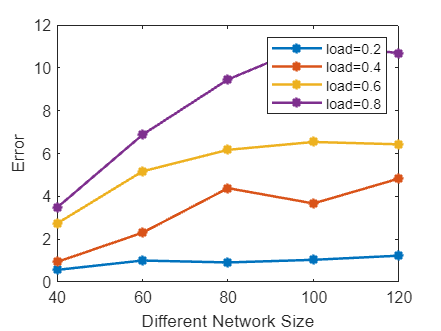

clc;
close all;
import ELSclique.*
rng(4)
N=[40 60 80 100 120];
M=6;
load_choice=[0.2 0.4 0.6 0.8];
%box_size=[2 3 4 5 6];
for i1=1:length(load_choice)
    error_network=zeros(1,length(N));
    for i2=1:length(N)
        N1=N(i2);
        x=rand(1,N1)*5;
        y=rand(1,N1)*5;
        
        %scatter(x,y)
        %Distance of the nodes
        d=zeros(N1,N1);
        for i=1:N1
            for j=i+1:N1
                d(i,j)=sqrt((x(j)-x(i))^2+(y(j)-y(i))^2);
                d(j,i)=d(i,j);
            end
        end
        
        %Selecting those nodes for edges which has distance less than or equal
        % to 1
        
        A=zeros(N1);
        for i=1:N1
            for j=i+1:N1
                if d(i,j)<=1
                    A(i,j)=1;
                    A(j,i)=1;
                end
            end
        end
        
        [cliques]=ELSclique(A);
        log_cliques=full(cliques);
        clique_size=zeros(1,size(log_cliques,2));
        for i=1:length(clique_size)
             for j=1:size(log_cliques,1)
                if log_cliques(j,i)==1
                    clique_size(i)=clique_size(i)+1;
                end    
             end 
        end 
        %figure(2)
        %G=graph(A);
        %plot(G,"XData",x,"YData",y)
        %{
        Adjust the adjacency matrix to ensure no clique is larger than the
        maximum clique size
        %}
        for i = 1:size(log_cliques, 2)
            cliqueNodes = find(log_cliques(:, i)==1);
            if length(cliqueNodes) > 10
                % Remove edges to break the clique
                cliqueEdges = nchoosek(cliqueNodes, 2);
                for j = 1:size(cliqueEdges, 1)
                    A(cliqueEdges(j, 1), cliqueEdges(j, 2)) = 0;
                    A(cliqueEdges(j, 2), cliqueEdges(j, 1)) = 0;
                end
            end
        end
        
        [cliques_re]=ELSclique(A);
        log_cliques_re=full(cliques_re);
        clique_size_re=zeros(1,size(log_cliques_re,2));
        for i=1:length(clique_size_re)
             for j=1:size(log_cliques_re,1)
                if log_cliques_re(j,i)==1
                    clique_size_re(i)=clique_size_re(i)+1;
                end    
             end 
        end

        w_G=max(clique_size_re);
        s_rmax=min([1 M/w_G]);
        load=load_choice(i1);
        S_desired=load*s_rmax;
        ui=S_desired/M;
        uj=S_desired/M;
        exp_ri=zeros(1,N1);
        for i=1:N1
            li=find(A(i,:)==1);
            di=length(li);
            uij=(ui+uj-1+sqrt(4*(M-1)*ui*uj+(ui+uj-1)^2))/(2*(M-1));
            Prod=ones(1,di)*((ui-(M-1)*uij)/(1-M*(ui+uj-(M-1)*uij)));
            exp_ri(i)=(((1-M*ui)/ui)^(di-1))*prod(Prod);
        end
        num_iter=1e7;
        B=zeros(num_iter,N1);
        for i=2:size(B,1)
            index=1:N1;
            j=randi(N1);
            index(j)=[];
            a=find(A(j,:)==1);
            Ch=1:M;
            a_ch=B(i-1,a);
            a_ch=unique(a_ch);
            rem_ch=Ch(~ismember(Ch,a_ch));
            if isempty(rem_ch)
                B(i,j)=0;
                B(i,index)=B(i-1,index);
                continue
            end
            p0=1/(1+length(rem_ch)*exp_ri(j));
            p1=1-(1/(1+length(rem_ch)*exp_ri(j)));
            %state=[0 rem_ch];
            %P1=ones(1,length(rem_ch));
            %P1=P1*(p1/length(rem_ch));
            %probabilities=[p0 P1];
            %s=randsample(state,1,true,probabilities);
            random=rand;
            if random>p1
               B(i,j)=0;
               B(i,index)=B(i-1,index);
            else
                B(i,j)=rem_ch(randi(length(rem_ch)));
                B(i,index)=B(i-1,index);
            end
        end

        S_rempirical=zeros(1,N1);
        for i=1:N1
            on=transpose(find(B(:,i)>0));
            S_rempirical(i)=length(on)/num_iter;
        end
        el_error=zeros(1,N1);
        for i=1:N1
            error_ch=[S_desired-S_rempirical(i) 0];
            el_error(i)=max(error_ch)/S_desired;
        end
        error_network(i2)=(100/N1)*sum(el_error);
    end
    plot(N,error_network,"-*","LineWidth",1.5)
    xlabel("Different Network Size")
    ylabel("Error")
    hold on
end
legend("load=0.2","load=0.4","load=0.6","load=0.8")